# Initialization


k1=10.9 %constant

k1 = 10.9000

k2=104.405 % constant

k2 = 104.4050

Ra=1.278 % constant

Ra = 1.2780

Imax=5  % constant

Imax = 5

vsupply=6.3%variable

vsupply = 6.3000

tload=0.040845 % constantish

tload = 0.0408

fluxmWb=0.0937010533 %constant

fluxmWb = 0.0937

fluxmWbrangemax = 50 % range the fluxmWb is in)

fluxmWbrangemax = 50

runmultpleflux =1 %while true runs 4 different flux value the calculated value within the range

runmultpleflux = 1

% , very computationly expensive, while false runs calculated flux
J= 2.3939*10^-4 % constant

J = 2.3939e-04

numberofpoints=10000 %variable

numberofpoints = 10000

maxtime=15 %variable

maxtime = 15

t=linspace(0,maxtime,numberofpoints); %initalizing time

## Using ODE instead to calcualte rotational speed using runge kutta method

%%{
count =runmultpleflux *3 +1 ;% either do one run, or four runs ;
rangeofFluxpercent = linspace(0,fluxmWbrangemax,4);
fluxRangemWb = fluxmWb + fluxmWb.*rangeofFluxpercent/100;
rotationspeed = zeros([count,numberofpoints]);
j=1;
while (j<=count)
flux = [fluxRangemWb(1,j)/1000];
part1a  = 60*k2*flux*vsupply/(2*pi()*Ra*J); %creating differential 
part2a = 60*tload/(2*pi()*J); %creating differential
part3a = (60*k2*k1*flux^2)/(2*pi()*Ra*J); %creating differential

dspeeddt = @(speed) part1a-part2a-part3a*(speed); %created differential
speed = zeros([1 length(t)]); %intilizing speed, at (t=0,speed=0)
h= maxtime/numberofpoints; %intilizing delta t, or timestep
%runge kutta 4th order method 
for i=1:(length(t)-1)
    c1=h*dspeeddt(speed(1,i));
    c2= h*dspeeddt(speed(1,i)+c1/2);
    c3= h*dspeeddt(speed(1,i)+c2/2);
    c4=h*dspeeddt(speed(1,i)+c3);
    speed(1,i+1) = speed(1,i)+(1/6)*(c1+2*c2+2*c3+c4);
end
rotationspeed(j,:)=speed;
j=j+1;
%}
end

## All calculations for all values

[emf,current,tinduced,Mechpower,Pelect,Pload,efficiency]=deal(zeros([count,numberofpoints]));
fluxrange = fluxRangemWb/1000;
for l=1:count
emf(l,:) = k1*fluxrange(1,l)*rotationspeed(l,:); %calculating emf
current(l,:) =(vsupply-emf(l,:))./Ra; %calculating current
tinduced(l,:) = k2*fluxrange(1,l)*current(l,:); % tinduced using formula
Mechpower(l,:) =2*pi()*tinduced(l,:).*(rotationspeed(l,:)/60); % mech power using formula
Pelect(l,:) =vsupply*current(l,:); %power supplied
Pload(l,:) = tload*2*pi()*(rotationspeed(l,:)/60); % power used by load
efficiency(l,:) = ((Mechpower(l,:)-Pload(l,:) )*100)./Pelect(l,:); % efficiency using formula
end
%printing stuff using sprintf
maxspeed=round(max(rotationspeed,[],'all'),5,'significant')

maxspeed = 1.7903e+03

maxcurrentused=max(current,[],'all');
maxcurrentused=round(maxcurrentused,4,'significant')

maxcurrentused = 4.9300

if maxcurrentused>Imax-10^-5
    formatSpec1 = 'The current limit of %g amps has been breached.';
    str = sprintf(formatSpec1,Imax);
else 
    formatSpec1 = 'The current has not been breached and has a value of %g amps';
    str = sprintf(formatSpec1,maxcurrentused);
end
if max(rotationspeed>2000)
    formatSpec2 = 'The speed limit of 2000rpm has been breached at a value of %grpm.';
    str2 = sprintf(formatSpec2,maxspeed);
else 
    formatSpec2 = 'The speed limit of 2000rpm has not been breached and has a value of %grpm.';
    str2 = sprintf(formatSpec2,maxspeed);
end

## Rudimentary plotting

fprintf(str);

The current has not been breached and has a value of 4.93 amps

fprintf(str2);

The speed limit of 2000rpm has not been breached and has a value of 1790.3rpm.

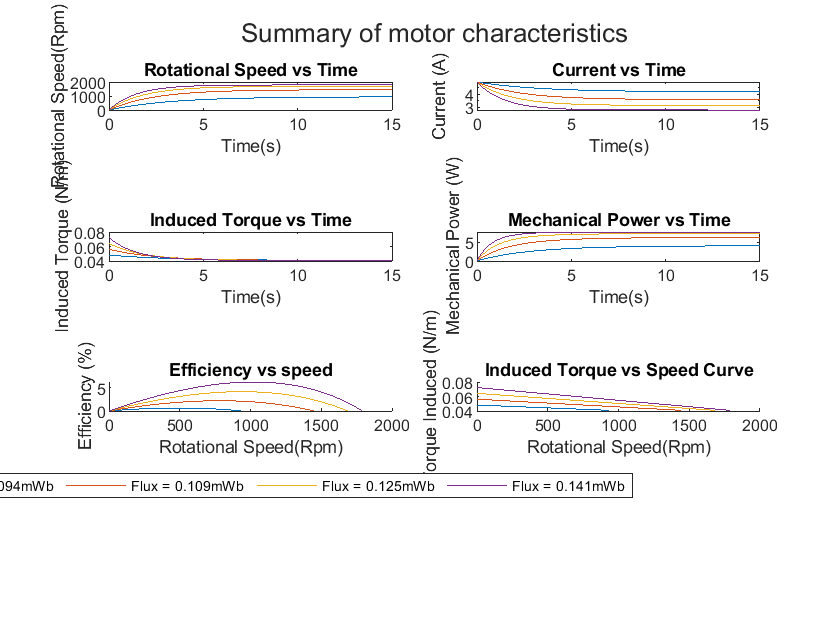

figure()
hold off
finalplot=tiledlayout(4,2,'TileSpacing','Compact'); %multiple plot figure
ax1=nexttile(); % plot first plot
plot(ax1,t,rotationspeed)
title(ax1,'Rotational Speed vs Time')
xlabel(ax1,'Time(s)')
ylabel(ax1,'Rotational Speed(Rpm)')

ax2=nexttile; %plot second plot
plot(ax2,t,current)
title(ax2,'Current vs Time')
xlabel(ax2,'Time(s)')
ylabel(ax2,'Current (A)')

ax3=nexttile; % plot third plot
plot(ax3,t,tinduced(:,:))
title(ax3,'Induced Torque vs Time')
xlabel(ax3,'Time(s)')
ylabel(ax3,'Induced Torque (N/m)')

ax4=nexttile; % plot fourth plot
plot(ax4,t,Mechpower)
title(ax4,'Mechanical Power vs Time')
xlabel(ax4,'Time(s)')
ylabel(ax4,'Mechanical Power (W)')

ax5=nexttile; % plot rotationspeed vs efficiency,(plot each efficiency vs speed)
for n = 1:count
    hold on
    plot(ax5,rotationspeed(n,:),efficiency(n,:))
end
hold off
title(ax5,'Efficiency vs speed')
xlabel(ax5,'Rotational Speed(Rpm)')
ylabel(ax5,'Efficiency (%)')

ax6=nexttile; % plot torque vs rotationspeed,(plot each torque vs rotationspeed)
for n= 1:count 
    hold on
    plot(ax6,rotationspeed(n,:),tinduced(n,:))
end
hold off
title(ax6,'Induced Torque vs Speed Curve')
xlabel(ax6,'Rotational Speed(Rpm)')
ylabel(ax6,'Torque Induced (N/m)')
title(finalplot,'Summary of motor characteristics');
fluxStr = string(round(fluxRangemWb(1:count),3));
listflux=append('Flux = ',fluxStr,'mWb');
lh =legend(ax5,listflux,'Location','SouthOutside','Orientation','Horizontal');